# LAMINATE THEORY

## Input Parameters

a = 30:1:75 ; % Fiber orientation α angle for layers 1 & 3 (degrees)
b = 30:1:75 ; % Fiber orientation β angle for layers 1 & 3 (degrees)
twist_angles = zeros(length(a), length(b)); % initialize matrix to store twist angles
t = 0.25*10^-3 ;% Thickness of the layer (m)
R = 25*10^-3 ; % Radius of the mandrel (m)
L = 300*10^-3 ; % Length of the tube (m)
P = -25000 ; % Compressive load applied (N)
C = 2*pi*R ; % Circumference of the tube (m)
E_1 = 236*10^9 ; % Longitudinal Young's modulus (pascals)
E_2 = 5*10^9 ; % Transverse Young's modulus (pascals)
G_12 = 2.66*10^9 ; % Longitudinal Shear modulus (pascals)
v_12 = 0.25 ; % Longitudinal Poisson's ratio
v_21 = v_12*(E_2/E_1); % Transverse Poisson's ratio
sigma_1t = 3800*10^6 ; % Longitudinal Tensile strength (strength/pascals)
sigma_1c = 689*10^6 ; % Longitudinal Compressive strength (strength/pascals)
sigma_2t = 41*10^6 ; % Transverse Tensile strength (strength/pascals)
sigma_2c = 107*10^6 ; % Transverse Compressive strength (strength/pascals)
tau_12 = 69*10^6 ; % Longitudinal Shear strength (strength/pascals)

# Optimum Twist angle

## Initialisation

% Generalised Stress Matrix [N]
N_x = [P/(2*pi*R); 0; 0];

% MAterial Stiffness matrix [Q]
Q = [(E_1/(1-(v_12*v_21))) ((v_12*E_2)/(1-(v_12*v_21))) 0; ((v_21*E_1)/(1- (v_12*v_21))) (E_2/(1-(v_12*v_21))) 0; 0 0 G_12];

% Condition to find the max twist angle
for i = 1:length(a) % loop condition to calculate the matrices depending on angle alpha for i th iterations

    % Trignometric Functions used in the calculations for layers 1 & 3
    a_rad = deg2rad(a(i)); % α angle degrees into radians conversion
    a_cos = cos(a_rad);
    a_sin = sin(a_rad);
    a_cos2 = a_cos^2;
    a_sin2 = a_sin^2;
    a_2cos_sin = 2*a_cos*a_sin;
    a_cos2_sin2 = cos(2*a_rad);
    % Transformation matrix for layer 1 & 3
    T_a = [a_cos2 a_sin2 -a_2cos_sin; a_sin2 a_cos2 a_2cos_sin; a_2cos_sin/2  -a_2cos_sin/2  a_cos2_sin2];

    % Transformed lamina stiffness matrix layer 1 & 3
    Q_a = T_a*Q*transpose(T_a);
    for j = 1:length(b) % loop condition to calculate the matrices depending on angle beta for j th iterations

        % Trignometric Functions used in the calculations for layers 2 & 4
        b_rad = deg2rad(b(j)); % β angle degrees into radians conversion
        b_cos = cos(b_rad);
        b_sin = sin(b_rad);
        b_cos2 = b_cos^2;
        b_sin2 = b_sin^2;
        b_2cos_sin = 2*b_cos*b_sin;
        b_cos2_sin2 = cos(2*b_rad);

        % Transformation matrix for layer 2 & 4
        T_b = [b_cos2 b_sin2 -b_2cos_sin; b_sin2 b_cos2 b_2cos_sin;
            b_2cos_sin/2 -b_2cos_sin/2 b_cos2_sin2];

        % Transformed lamina stiffness matrix layer 2 & 4
        Q_b = T_b*Q*transpose(T_b);

        % Laminate Stiffness Matrix [A]
        A = 2*t*(Q_a + Q_b);

        % Inverse Matrix of Laminate stiffness matrix [A]
        A_inv = inv(A);

        % To find shear strain, the shear membrane has been calculated
        strain_membrane = (A_inv)*N_x; % The third element of this vector is shear strain ~ strain_membrane(3)

        % set of Twist angles for all four layers
        twist_angles(i, j) = rad2deg(strain_membrane(3)*L/R); % twist angle in matrix (degrees)

    end % loop end condition for β angle
end % loop end condition for α angle

# Plots (*α* Vs *β* Vs Twist Angle)

## Surface Plot

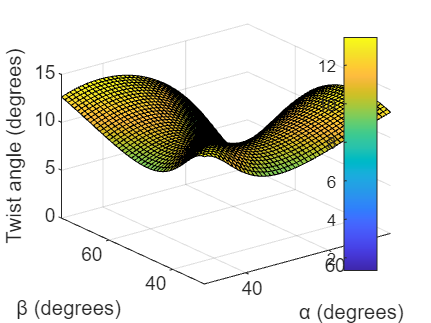

surf(a ,b,twist_angles)
colorbar('east')
xlabel('α (degrees)');
ylabel('β (degrees)');
zlabel('Twist angle (degrees)');

## Contour Plot

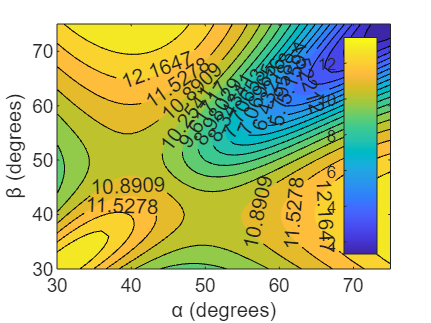

contourf(a,b, twist_angles, 'ShowText','on', 'LevelList', linspace(min(twist_angles(:)), max(twist_angles(:)), 20))
colorbar ('east')
xlabel('α (degrees)');
ylabel('β (degrees)');
zlabel('Twist angle (degrees)');

## Maximum Twist Angle

[max_twist, max_idx] = max(twist_angles(:));
[row_idx, col_idx] = ind2sub(size(twist_angles), max_idx); 
fprintf('The maximum twist angle is %f at row %d, column %d\n', max_twist, row_idx, col_idx)

The maximum twist angle is 13.438466 at row 46, column 10



a_max = a(col_idx); % α @ maximum twist angle
b_max = b(row_idx); % β @ maximum twist angle
fprintf('Fibre orientation at maximum twist angle: α =%f, β =%f\n', a_max, b_max);

Fibre orientation at maximum twist angle: α =39.000000, β =75.000000


# Maximum Failure Stress Criterion at Max Twist Angle

## Initialisation

% Degrees to Radians conversion
a_max_rad = deg2rad(a_max);
b_max_rad = deg2rad(b_max);

% Trignometric Functions used in the calculations for fiber orientation in layers 1 & 3 @ Max Twist angle
a_cos_max = cos(a_max_rad);
a_sin_max = sin(a_max_rad);
a_cos2_max = a_cos_max^2;
a_sin2_max = a_sin_max^2;
a_2cos_sin_max = 2*a_cos_max*a_sin_max;
a_cos2_sin2_max = cos(2*a_max_rad);

% Trignometric Functions used in the calculations for fiber orientation in layers 2 & 4 @ Max Twist angle
b_cos_max = cos(b_max_rad);
b_sin_max = sin(b_max_rad);
b_cos2_max = b_cos_max^2;
b_sin2_max = b_sin_max^2;
b_2cos_sin_max = 2*b_cos_max*b_sin_max;
b_cos2_sin2_max = cos(2*a_max_rad);

% Transformation matrix for layer 1 & 3 @ maximum twist angle
T_a_max = [a_cos_max a_sin_max -a_2cos_sin_max; a_sin_max a_cos_max a_2cos_sin_max; a_2cos_sin_max/2 -a_2cos_sin_max/2 a_cos2_sin2_max];

% Transformed lamina stiffness matrix layer 1 & 3 @ maximum twist angle
Q_a_max = T_a_max*Q*transpose(T_a_max);

% Transformation matrix for layer 2 & 4 @ maximum twist angle
T_b_max = [b_cos_max b_sin_max -b_2cos_sin_max; b_sin_max b_cos_max b_2cos_sin_max; b_2cos_sin_max/2 -b_2cos_sin_max/2 b_cos2_sin2_max]; 

% Transformed lamina stiffness matrix layer 2 & 4 @ maximum twist angle
Q_b_max = T_b_max*Q*transpose(T_b_max);

% Laminate stiffness matrix [A] @ maximum condition
A_max = 2*t*(Q_a_max+Q_b_max);

% Inverse Matrix of Laminate stiffness matrix [A] @ maximum condition
A_inv_max = inv(A_max);

% Shear membrane @ maximum condition
strain_membrane_max = (A_inv_max)*N_x; 
Strain_a_max = transpose(T_a_max)*(strain_membrane_max); % Strain value for α max at the principal axis
Strain_b_max = transpose(T_b_max)*(strain_membrane_max); % Strain value for β max at the principal axis
stress_a_max = (Q)*(Strain_a_max); % Stress value for α max at the principal axis
stress_b_max = (Q)*(Strain_b_max); % Stress value for β max at the principal axis

## Longitudinal stress criterion

format default
% Maxmum failure criterion based on the stress values calculated @ max twist angle
if (stress_a_max(1)<0)
    FMS_a_1_max = (abs(stress_a_max(1)/sigma_1c))
else
    FMS_a_1_max = (stress_a_max(1)/sigma_1t)
end

FMS_a_1_max = 0.3595

if (stress_b_max(1)<0)
    FMS_b_1_max = (abs(stress_b_max(1)/sigma_1c))
else
    FMS_b_1_max = (stress_b_max(1)/sigma_1t)
end

FMS_b_1_max = 0.0514

## Transversal stress criterion

if (stress_a_max(2)<0)
    FMS_a_2_max = (abs(stress_a_max(2)/sigma_2c))
else
    FMS_a_2_max = (stress_a_max(2)/sigma_2t)
end

FMS_a_2_max = 0.7597

if (stress_b_max(2)<0)
    FMS_b_2_max = (abs(stress_b_max(2)/sigma_2c))
else
    FMS_b_2_max = (stress_b_max(2)/sigma_2t)
end

FMS_b_2_max = 0.7229

## Shear stress criterion

if (stress_a_max(3)<0)
    FMS_a_3_max = (abs(stress_a_max(3)/tau_12))
else
    FMS_a_3_max = (stress_a_max(3)/tau_12)
end

FMS_a_3_max = 0.5659

if (stress_b_max(3)<0)
    FMS_b_3_max = (abs(stress_b_max(3)/tau_12))
else
    FMS_b_3_max = (stress_b_max(3)/tau_12)
end

FMS_b_3_max = 0.3562

# Tape Measurement

a_1 = sin(a_max_rad);
b_1 = sin(b_max_rad);

W_a = (C * a_1)*1000 % Width of the tape for α at maximum twist angle

W_a = 98.8534

W_b = (C * b_1)*1000 % Width of the tape for β at maximum twist angle

W_b = 151.7273